direction_names = ["FF","BF","FB","BB"];

s = sysf_two_link_lowRe;
nlinks = length(s.geometry.linklengths);

s = ensure_connection_and_metric(s); % required for create_grids
s = create_grids(s)

s = struct with fields:
      geometry: [1×1 struct]
          noop: 1
         n_dim: 1
        visual: [1×1 struct]
       physics: [1×1 struct]
             A: @(alpha1)LowRE_local_connection(s.geometry,s.physics,[alpha1])
        metric: @(alpha1)LowRE_dissipation_metric(s.geometry,s.physics,[alpha1])
    grid_range: [-3.1000 3.1000]
       density: [1×1 struct]
      tic_locs: [1×1 struct]
         A_num: @(alpha1)LowRE_local_connection(s.geometry,s.physics,[alpha1])
          grid: [1×1 struct]


a_grid = s.grid.eval{1};
adot_grid = s.grid.eval{1}*0.1;

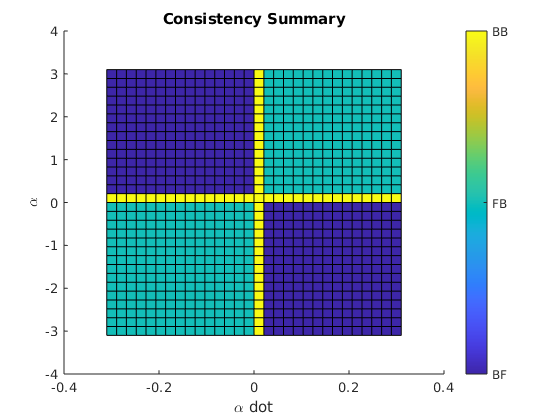

% find which system is consistent when
[system_map, count] = identify_piecewise_system(s, adot_grid);

% look at symmetry and missing/redundant areas
figure(5);
clf(5);
title("Consistency Summary");
xlabel("\alpha dot");
ylabel("\alpha");
surface(adot_grid, a_grid, system_map);
colorbar('Ticks',[1, 2, 3, 4],...
         'TickLabels',direction_names)

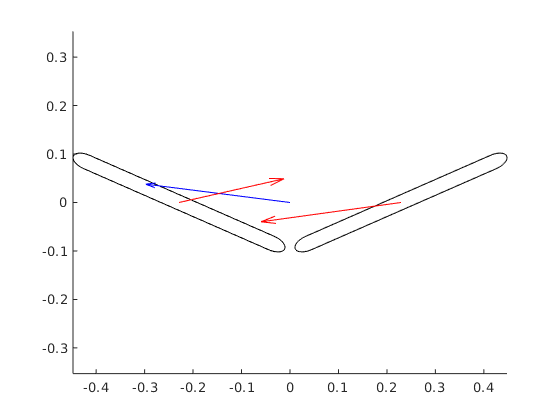

% get a body velocity
i = 20; j = 30;
bvel = apply_piecewise_system(s, system_map, 2, 0.1);

% get link velocities
lvel = zeros(nlinks, 3); % 3 is x y theta

% get Jfull(alpha)
[~, ~, J_full, ~, ~] = N_link_chain(s.geometry, a_grid(i));

for link = 1:nlinks
    lvel(link, :) = J_full{link} * [bvel; adot_grid(j)];
end

% plot
velocity_diagram(s, lvel, bvel, a_grid(i), adot_grid(j), 0, 0);

% animation testing

% apply ODE solver
t0 = 0;
tf = 2*pi;
g0 = [0 0 0];
[t_solution, g_solution] = ode45(@(t, g) calc_gdot(t, g, s, system_map), [t0, tf], g0);

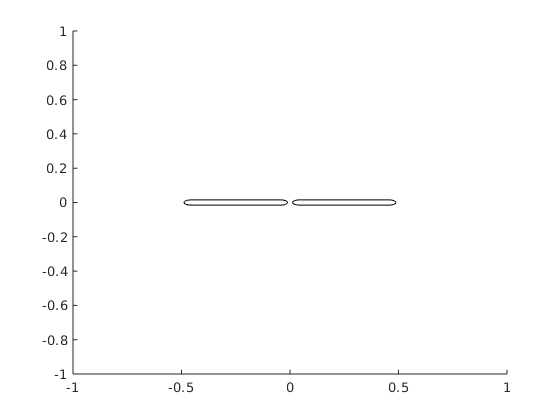

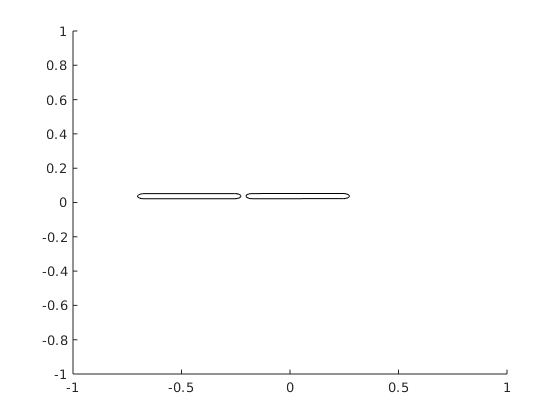

% record movie
figure()
axis manual
ax = gca;
ax.NextPlot = 'replaceChildren';
xlim([-1, 1]);
ylim([-1, 1]);

nframes = size(t_solution);
F = struct('cdata',[],'colormap',[]); % reset length of struct
F(nframes) = struct('cdata',[],'colormap',[]);
for frame = 1:nframes
    g = g_solution(frame, :);
    t = t_solution(frame);
    B = vec_to_mat_SE2(g) * fat_chain(s.geometry, gait(t));
    cla
    hold on
    patch(B(1,:),B(2,:),[1 0 0])
    drawnow
    F(frame) = getframe;
end

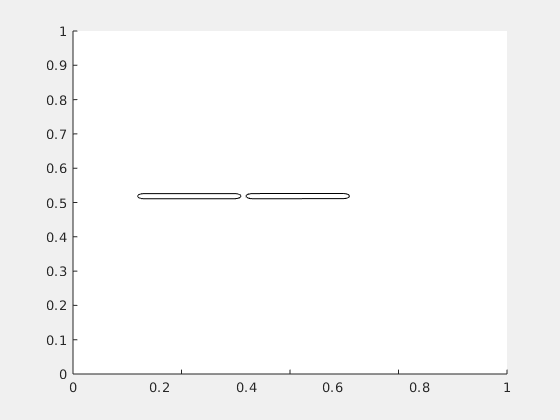

% play movie
figure('visible','on') %forces animation visible in live script
movie(F);

% write movie
% v = VideoWriter('AsymmetricFriction/animation_test_2link.avi');
% open(v);
% writeVideo(v, F);
% close(v);

% It's animating something!
% Things to do:
% - play around with different gaits
% - have body origin path traced out during animation
% - add motion blur
% - test with no-scales snake (physics check)
% - compare animation to physical intuition
%   (make sure scales are going in the correct direction)
% - move animation to function
% - store gaits so it's easy to manage multiple (gait files?)

function a = gait(t)
    a = 3 * sin(t);
end

function adot = gait_change(t)
    adot = 3 * cos(t);
end

function gdot = calc_gdot(t, g, s, system_map)
    gdot = TeLg(g) * apply_piecewise_system(s, system_map, gait(t), gait_change(t));
end